clear all;
clc;

function y = normalize2uint8(x)
    x = real(x);
    min_value = min(reshape(x,1,[]));
    max_value = max(reshape(x,1,[]));
    scale = 255./(max_value - min_value);
    bias = -1. * min_value * scale;
    y = scale * x + bias;
    y = uint8(y);
end

or_img = double(imread('CS270-Digitial-Image-Processing\project\dataset\shadow/_MG_6059.jpg'))/255;
hsv_img = rgb2hsv(or_img);

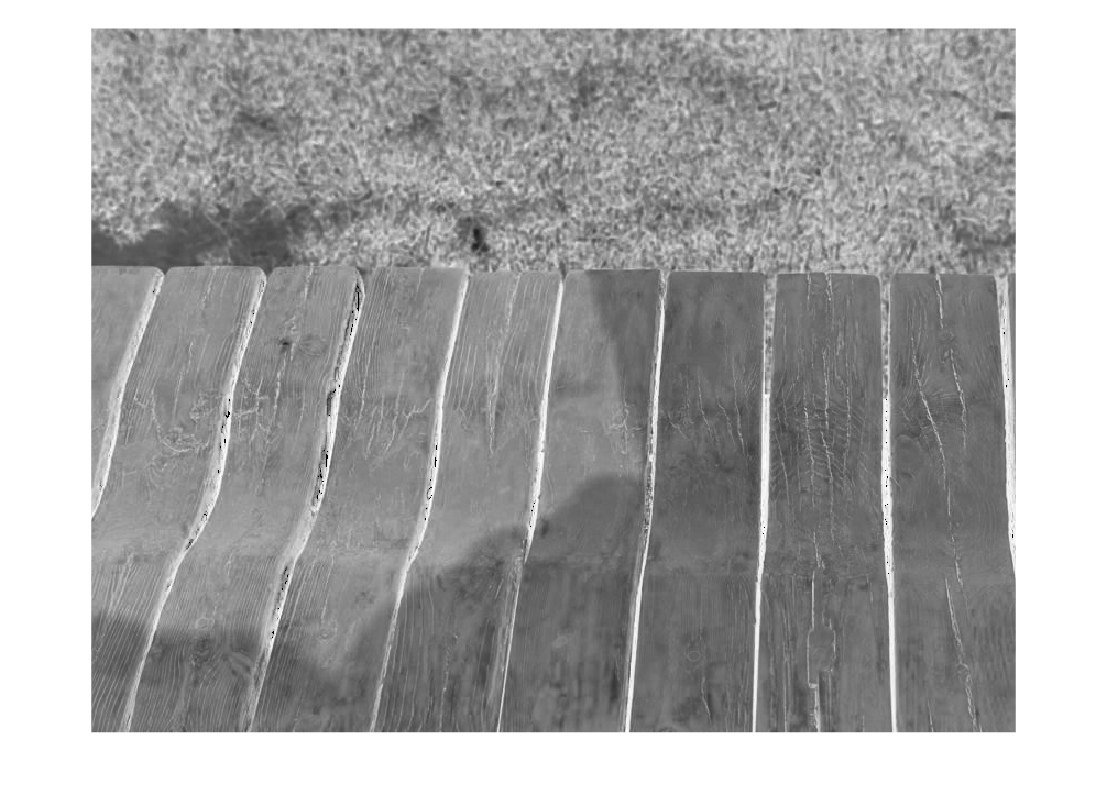

NSVDI = (hsv_img(:,:,2) - hsv_img(:,:,3))./(hsv_img(:,:,2) + hsv_img(:,:,3));
imshow(NSVDI,[]);

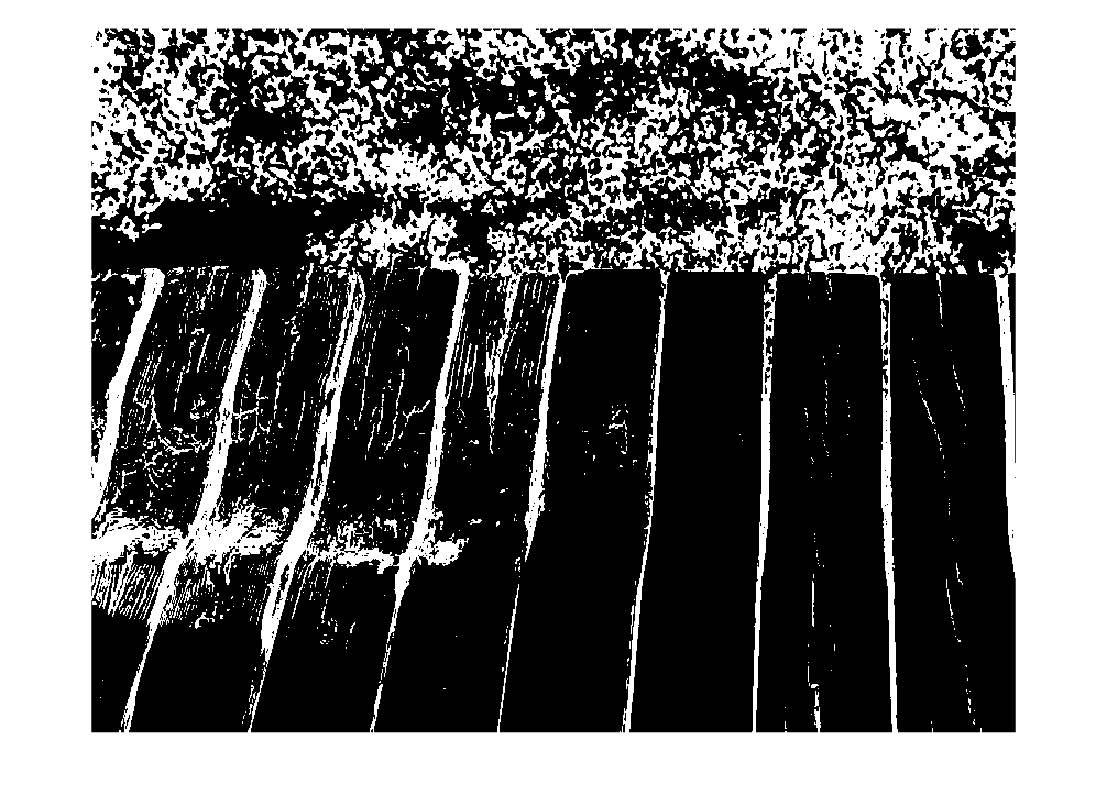

threshold = graythresh(NSVDI);
NSVDI_binary = NSVDI > threshold;
imshow(NSVDI_binary,[]);

% % 获取阴影和非阴影区域索引
% %shadow_pixels = find(NSVDI_binary == 1);
% %noshadow_pixels = find(NSVDI_binary == 0);
% shadow_pixels = or_img;
% noshadow_pixels = or_img;
% shadow_pixels(repmat(NSVDI_binary,[1,1,3]) == 0) = 0;
% noshadow_pixels(repmat(NSVDI_binary,[1,1,3]) == 1) = 0;
% % 计算阴影区域均值和方差
% 
% mu_s = mean(mean(shadow_pixels),2);
% sigma_s = std(std(shadow_pixels),2);

% % 计算非阴影区域均值和方差
% mu_n = mean(mean(noshadow_pixels,1),2);
% sigma_n = std(std(noshadow_pixels,1),2);
% 
% % 计算恢复系数
% lambda1 = sigma_n ./ sigma_s .* mu_s;
% lambda2 = mu_n - sigma_n ./ sigma_s .* mu_s;


n = 3;
R_x = double(or_img);
for i = 1:size(NSVDI_binary,1)
    for j = 1:size(NSVDI_binary,2)
        if NSVDI_binary(i,j) == 1
            % 找n*n邻域
            top = i - floor((n-1)/2);
            if top < 1
                top = 1;
            end
            left = j - floor((n-1)/2);
            if left < 1
                left = 1;
            end
            right = j + floor((n-1)/2);
            if right >= size(NSVDI,2)
                right = size(NSVDI,2);
            end
            btm = i + floor((n-1)/2);
            if btm >= size(NSVDI,1)
                btm = size(NSVDI,1);
            end
            omega = or_img(top:btm,left:right,:);
            M = max(omega,[],3);
            L_x = mean(M(:));

            binary_mask = NSVDI_binary(top:btm,left:right);
            for ch = 1:3
                omega_channel = omega(:,:,ch);
                mu_s = mean(omega_channel(binary_mask));
                sigma_s = std(omega_channel(binary_mask));

                mu_n = mean(omega_channel(~binary_mask));
                sigma_n = std(omega_channel(~binary_mask));
                lambda1 = sigma_n / sigma_s * mu_s;
                lambda2 = mu_n - sigma_n / sigma_s * mu_s;
                
                R_x(i,j,ch) = ((or_img(i,j,ch)-1+lambda1)/(1-1/lambda1+L_x))+1-lambda1;
                R_x(i,j,ch) = min(R_x(i,j,ch),1);
                R_x(i,j,ch) = max(R_x(i,j,ch),0);
            end
            

         
        end
    end
end

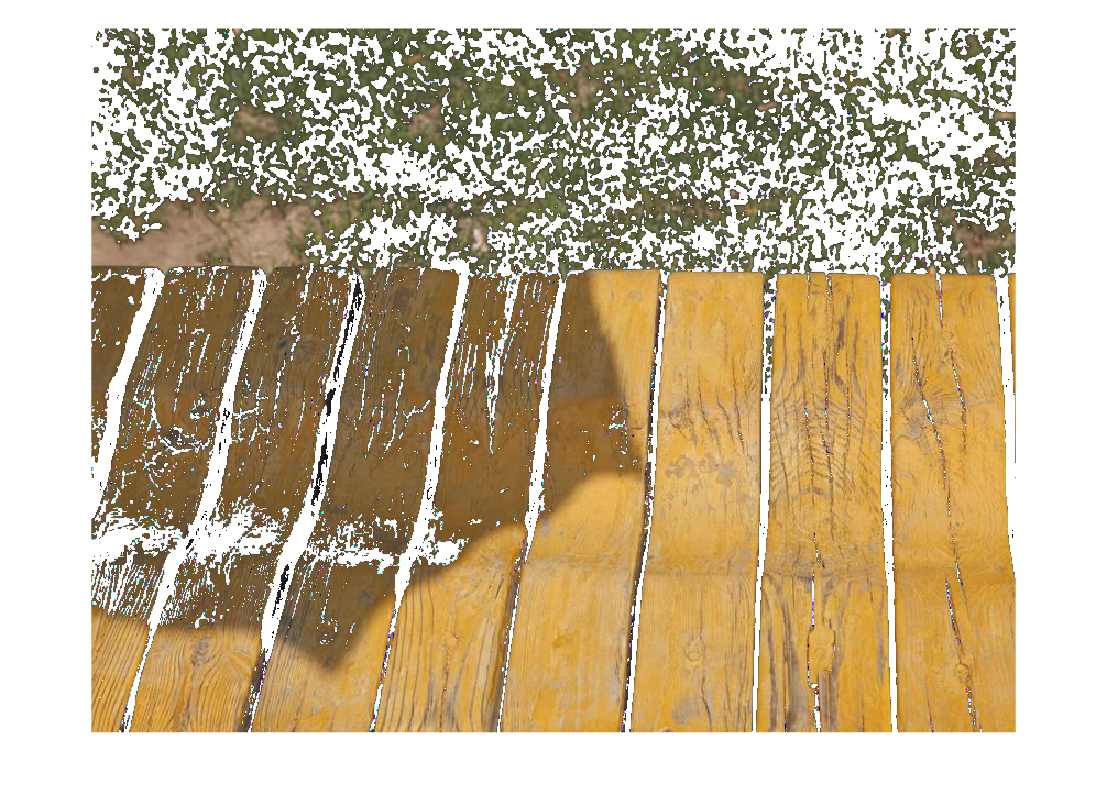

imshow(normalize2uint8(R_x),[]);

min(R_x(:))

ans = 0

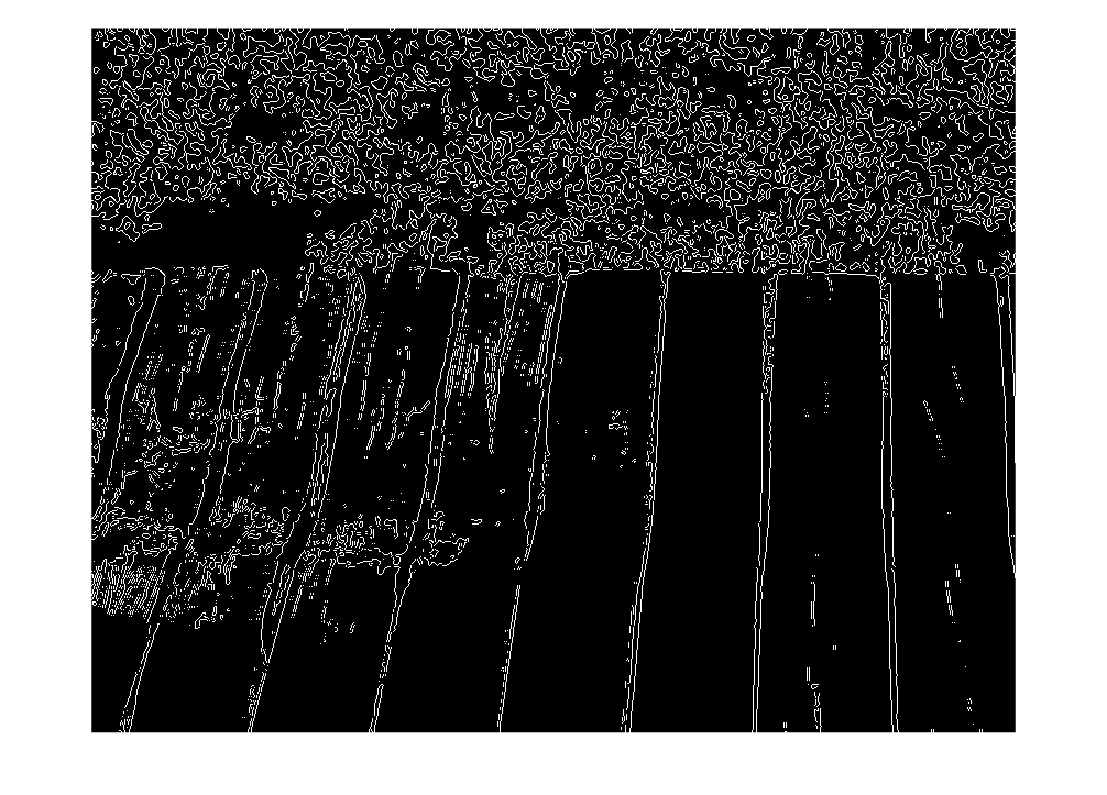

R_x_2 = R_x;
edge_mask = edge(NSVDI_binary,"sobel");
imshow(edge_mask,[]);

for i = 1:size(edge_mask,1)
    for j = 1:size(edge_mask,2)
        if edge_mask(i,j) == 1
            % 找n*n邻域
            top = i - floor((n-1)/2);
            if top < 1
                top = 1;
            end
            left = j - floor((n-1)/2);
            if left < 1
                left = 1;
            end
            right = j + floor((n-1)/2);
            if right >= size(edge_mask,2)
                right = size(edge_mask,2);
            end
            btm = i + floor((n-1)/2);
            if btm >= size(edge_mask,1)
                btm = size(edge_mask,1);
            end
            omega = R_x(top:btm,left:right,:);
            max_
            R_x_2(i,j,:) = ((R_x(i,j,:)-1+lambda1)/(1-1/lambda1+L_x))+1-lambda1;
        end
    end
end

函数或变量 'max_' 无法识别。